D=5.4cm

VappD1=[6.77 7.15 5.60 3.93 3.088];
IappD1=[2.232 2.287 2.015 1.688 1.509];
Vsensor1=[1.8 2.2 1.4 0.8 0.6]./(1000);
V1err=[0.01 0.01 0.01 0.01 0.01];
I1err=[1 1 1 1 1]./(1000);
Vs1err=[1 1 1 1 1]./(10000);
R1=VappD1./IappD1;
R1err=((V1err./VappD1).^2+(I1err./IappD1).^2).^(1/2);
Temp1=(156.2/ 0.2938).*R1+358.8;
logT1=log10(Temp1);
logV1=log10(Vsensor1);
logV1err = ((V1err./(log(10)*VappD1)))

logV1err =     0.0006    0.0006    0.0008    0.0011    0.0014


logT1err=(R1err./(log(10).*R1))

logT1err = 	1.0e+-3 *

    0.2210    0.2036    0.2896    0.4873    0.7015


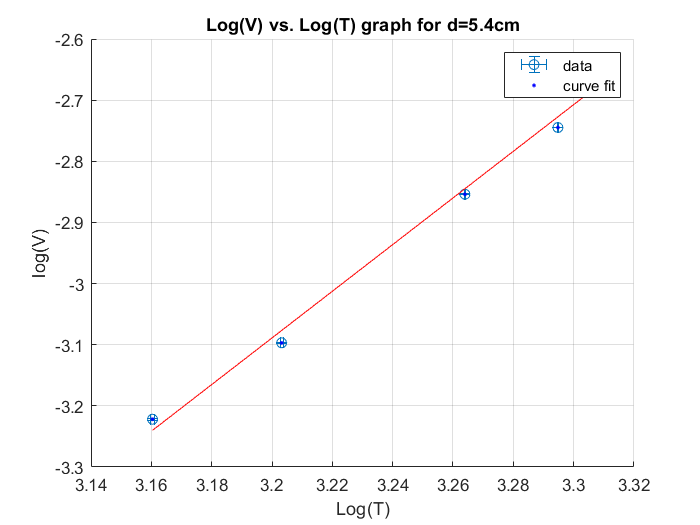




[xData, yData] = prepareCurveData( logT1, logV1 );
xpos=logT1err;
xneg=xpos;

ypos=logV1err;
yneg=ypos;

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
errorbar(logT1, logV1, yneg, ypos, xneg, xpos,'o')
h = plot( fitresult, xData, yData );
xlabel Log(T)
ylabel log(V)
grid on
title('Log(V) vs. Log(T) graph for d=5.4cm')
hold off

legend({'data','curve fit'})

Linear model Poly1:

     f(x) = p1*x + p2

Coefficients (with 95% confidence bounds):

       p1 =       5.786\pm0.458  

       p2 =       -20.2 \pm 0.90 

Goodness of fit:

  SSE: 0.001594

  R-square: 0.9935

  Adjusted R-square: 0.990

  RMSE: 0.02263

D=8.4cm

VappD2=[3.51 5.45 6.40 7.14 7.75];
IappD2=[1.601 1.995 2.162 2.285 2.386];
Vsensor2=[0.4 0.8 1.0 1.2 1.4]./(1000);
V2err=[0.01 0.01 0.01 0.01 0.01];
I2err=[1 1 1 1 1]./(1000);
Vs2err=[1 1 1 1 1]./(10000);
R2=VappD2./IappD2;
R2err=((V2err./VappD2).^2+(I2err./IappD2).^2).^(1/2);
Temp2=(156.2/ 0.2938).*R2+358.8;
logT2=log10(Temp2);
logV2=log10(Vsensor2);
logV2err = ((V2err./(log(10)*VappD2)))

logV2err =     0.0012    0.0008    0.0007    0.0006    0.0006


logT2err=(R2err./(log(10).*R2))

logT2err = 	1.0e+-3 *

    0.5778    0.3024    0.2391    0.2039    0.1814


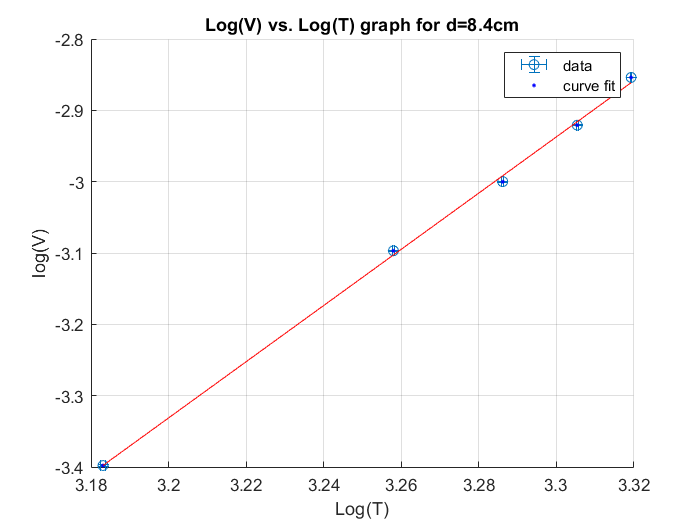




[xData, yData] = prepareCurveData( logT2, logV2 );
xpos=logT2err;
xneg=xpos;

ypos=logV2err;
yneg=ypos;

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
errorbar(logT2, logV2, yneg, ypos, xneg, xpos,'o')
h = plot( fitresult, xData, yData );
xlabel Log(T)
ylabel log(V)
grid on
title('Log(V) vs. Log(T) graph for d=8.4cm')
hold off
legend({'data','curve fit'})

Linear model Poly1:

     f(x) = p1*x + p2

Coefficients (with 95% confidence bounds):

       p1 =       5.876 \pm0.183

       p2 =      -20.23 \pm 0.42

Goodness of fit:

  SSE: 0.0001923

  R-square: 0.997

  Adjusted R-square: 0.9980

  RMSE: 0.007921

D=11.4cm

VappD3=[7.76 7.09 8.22 5.94 4.64];
IappD3=[2.386 2.274 2.458 2.075 1.832];
Vsensor3=[0.8 0.8 1.0 0.6 0.4]./(1000);
V3err=[0.01 0.01 0.01 0.01 0.01];
I3err=[1 1 1 1 1]./(1000);
Vs3err=[10^(-4) 10^(-4) 10^(-4) 10^(-4) 10^(-4)];
R3=VappD3./IappD3;
R3err=((V3err./VappD3).^2+(I3err./IappD3).^2).^(1/2);
Temp3=(156.2/ 0.2938).*R3+358.8;
logT3=log10(Temp3);
logV3=log10(Vsensor3);
logV3err = ((V3err./(log(10)*VappD3)))

logV3err = 	1.0e+-3 *

    0.5597    0.6125    0.5283    0.7311    0.9360


logT3err=(R3err./(log(10).*R3))

logT3err = 	1.0e+-3 *

    0.1810    0.2058    0.1666    0.2657    0.3812


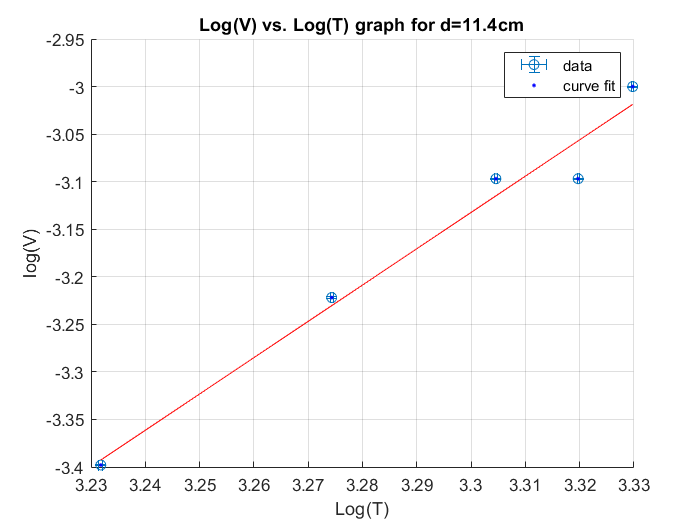



[xData, yData] = prepareCurveData( logT3, logV3 );
xpos=logT3err;
xneg=xpos;

ypos=logV3err;
yneg=ypos;
% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
errorbar(logT3, logV3, yneg, ypos, xneg, xpos,'o')
h = plot( fitresult, xData, yData );

% Label axes
xlabel Log(T)
ylabel log(V)
grid on
title('Log(V) vs. Log(T) graph for d=11.4cm')
hold off
legend({'data','curve fit'})

Linear model Poly1:

     f(x) = p1*x + p2

Coefficients (with 95% confidence bounds):

       p1 =       5.596 \pm0.854 

       p2 =      -19.22 \pm2.48

Goodness of fit:

  SSE: 0.002411

  R-square: 0.9750

  Adjusted R-square: 0.9698

  RMSE: 0.02857